#  Identify the Blue Colored Object in Cluttered Image

## Reading the  image and converting to HSV format 

% Read the input image

img = imread('waterbreathing.jpeg');

% Convert the image to HSV format 
hsv_img = rgb2hsv(img);

## Extraction of Hue, Saturation and Value 

% Extract the HSV values 
H = hsv_img(:, :, 1); 
S = hsv_img(:, :, 2);  
V = hsv_img(:, :, 3);  

% Define blue in HSV format 
blue_mask = (H >= 0.55 & H <= 0.75) & (S > 0.2) & (V > 0.2);

% Convert the image to grayscale 
gray_img = repmat(rgb2gray(img), [1, 1, 3]);

## Retaining only blue from the image 

% Obtain blue and keeping   other part of image to greyscale 
result_img = img;  
result_img(~repmat(blue_mask, [1, 1, 3])) = gray_img(~repmat(blue_mask, [1, 1, 3]));

## Display of image

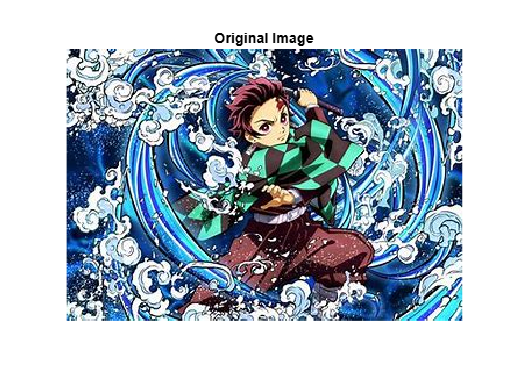

% Display or original and processed image 
figure;
imshow(img);
title('Original Image');

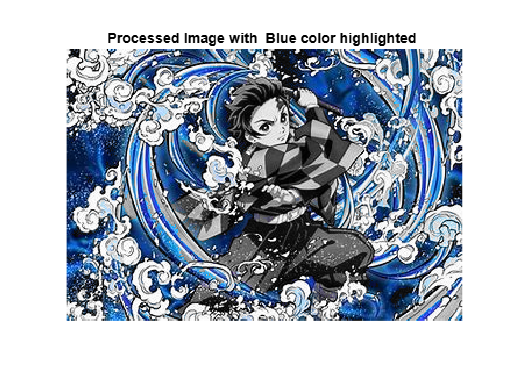


figure;
imshow(result_img);
title('Processed Image with  Blue color highlighted ');